# Introduction

Implementation of mean-field interacting diffusions using sde_euler in SDETools. 


$$dY_{t}^{i} = \alpha\left(\frac{1}{N} \sum_{j=1}^{N} Y_{t}^{j} - Y_{t}^{i}\right)dt + \sigma_{i}dW_{t}^{i}$$


% Add paths for SDETools
addpath 'C:\Users\Harry\OneDrive - Imperial College London\Imperial\Project\SDETools-master\SDETools'

## Parameters

dt = 1e-3;                                  % Step size 0.001
t = 0:dt:1;                                 % 1x101 time vector from 0 to 1
N = 10;                                     % Size of Y
y0 = zeros(N, 1);                           % Nx1 vector
y = y0;                                     % Nx1 vector         
alpha = ones(N, 1);                         % Nx1 vector of coefficients
sig = ones(N, 1);                           % Nx1 vector of volatilities
eta = -0.7;                                 % Default level
default_line = eta .* ones(length(t), 1);   % Default level
total_defaults = sum(min(y) <= -0.7);       % Total defaults

repeats = 500;
n_defaults = zeros(repeats, 1);

f = @(t, y) alpha.*(mean(y) - y); 
g = @(t, y) sig;

## Example of SDETools::sde_euler

Specify Ito, set random seed

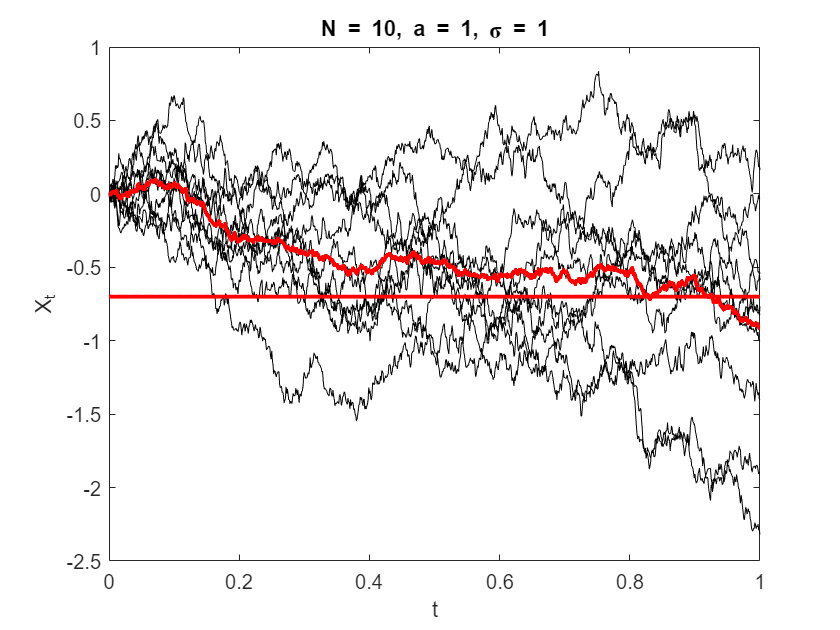

opts = sdeset('RandSeed', 10);         

% Use Euler-Maruyama to integrate SDEs
y = sde_euler(f, g, t, y0, opts);

ybar = mean(y, 2);

figure; 
plot(t, y, 'k')
hold on
% Average Line
plot(t, ybar, 'r', ...
    'LineWidth', 2)
hold on
% Default Line
plot(t, default_line, 'r', ...
    'LineWidth', 2)
hold off
title(["N = 10, a = 1, \sigma = 1"]);
xlabel('t'); ylabel('X_{t}');

# Baseline repeat

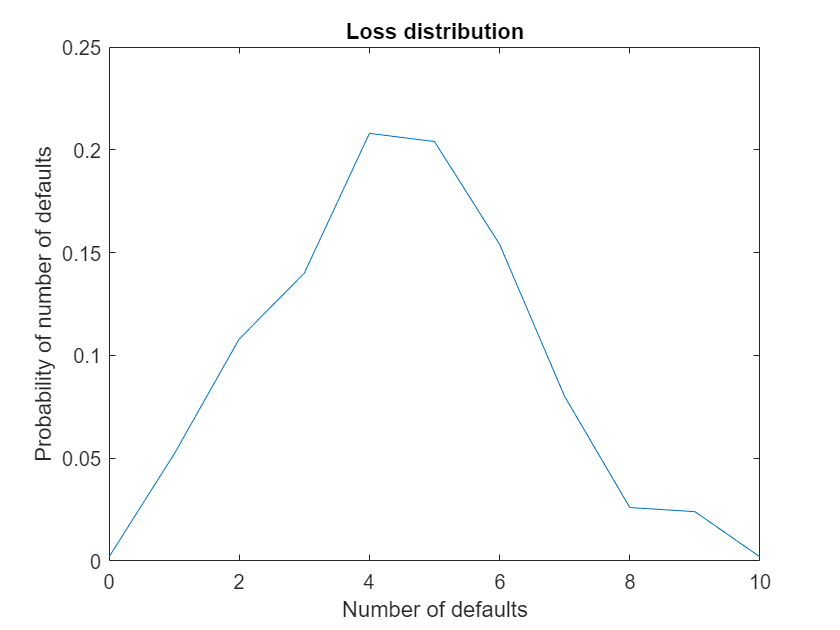

% Loop
for rep = 1:repeats
   % Specify Ito, set random seed
   opts = sdeset('RandSeed', rep);  
   y = sde_euler(f, g, t, y0, opts);
   n_defaults(rep) = sum(min(y) <= -0.7);
end

% Plot number of defaults
tbl = tabulate(n_defaults);
figure;
plot(tbl(:, 1), tbl(:, 3)/100);
title("Loss distribution")
xlabel('Number of defaults'); ylabel('Probability of number of defaults');

## Group A

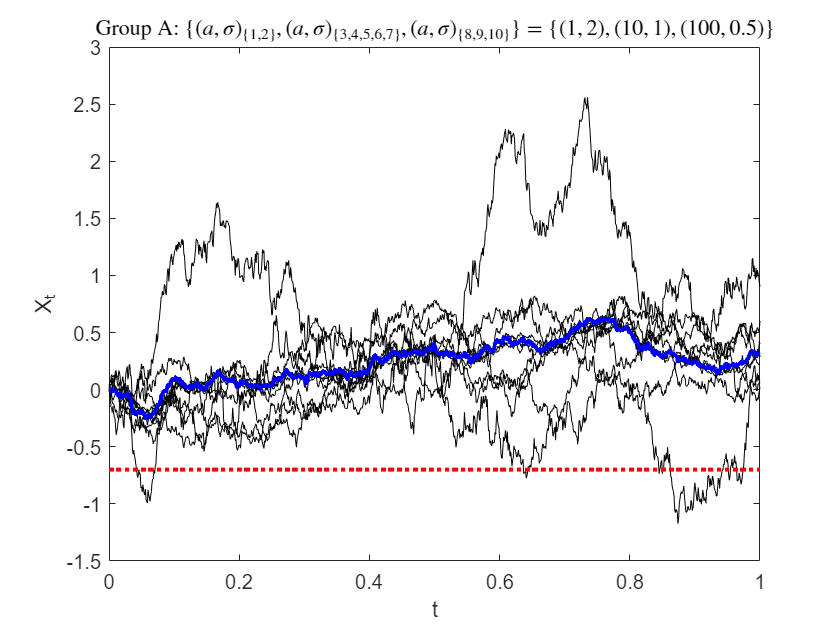

alpha = [repelem(1, 2, 1); repelem(10, 5, 1); repelem(100, 3, 1)];
sig = [repelem(2, 2, 1); repelem(1, 5, 1); repelem(0.5, 3, 1)];
f = @(t, y) alpha.*(mean(y) - y); 
g = @(t, y) sig;

% Loop
for rep = 1:repeats
   % Specify Ito, set random seed
   opts = sdeset('RandSeed', rep);  
   y = sde_euler(f, g, t, y0, opts);
   n_defaults(rep) = sum(min(y) <= -0.7);
end

ybar = mean(y, 2);

figure; 
plot(t, y, 'k')
hold on
% Average Line
plot(t, ybar, "blue", ...
    'LineWidth', 2)
hold on
% Default Line
plot(t, default_line, 'r', ...
    'LineWidth', 2, 'LineStyle', ':')
hold off
title('Group A: $\left\{(a, \sigma)_{\left\{1, 2\right\}}, (a, \sigma)_{\left\{3, 4, 5, 6, 7\right\}}, (a, \sigma)_{\left\{8, 9, 10\right\}} \right\} = \left\{(1, 2), (10, 1), (100, 0.5)\right\}$', ...
'interpreter', 'latex');
xlabel('t'); ylabel('X_{t}');

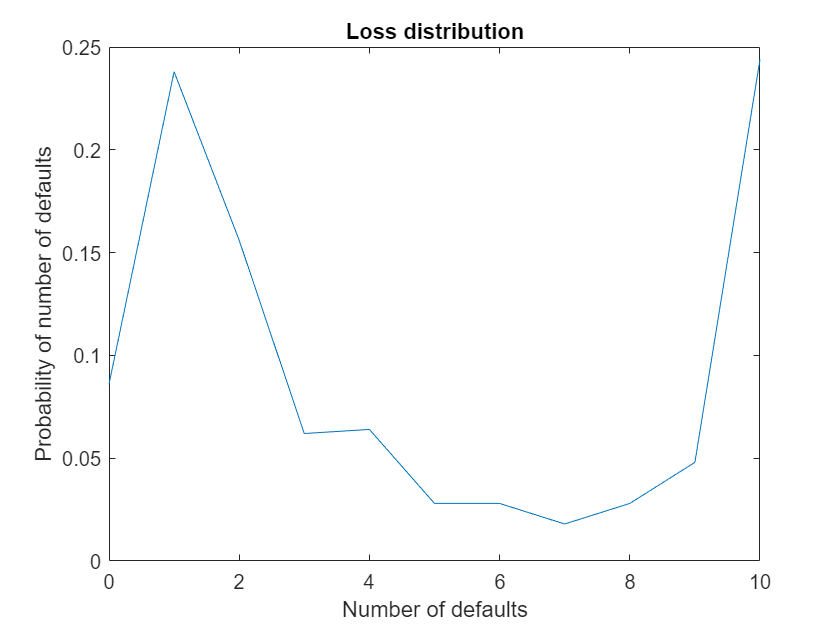


% Plot number of defaults
tbl = tabulate(n_defaults);
figure;
plot(tbl(:, 1), tbl(:, 3)/100);
title("Loss distribution")
xlabel('Number of defaults'); ylabel('Probability of number of defaults');

## Group B

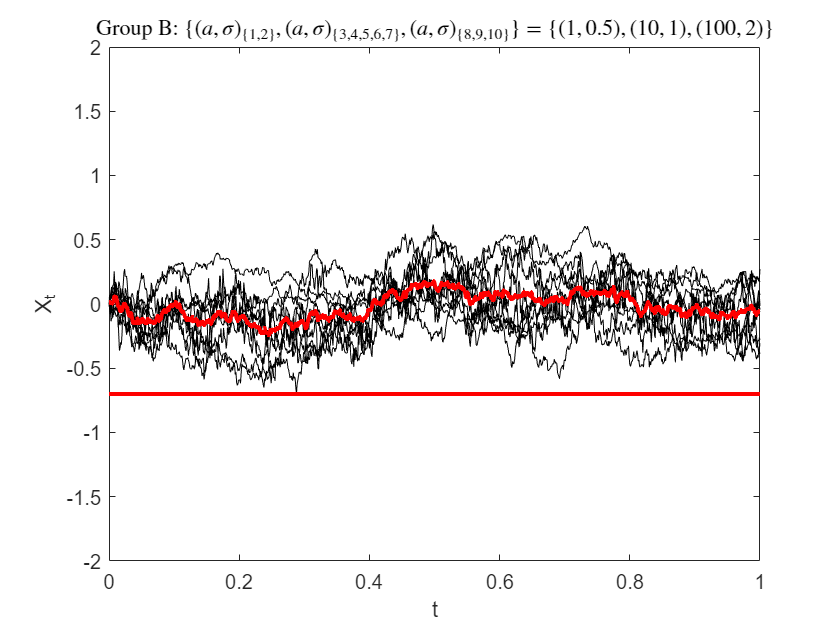

alpha = [repelem(1, 2, 1); repelem(10, 5, 1); repelem(100, 3, 1)];
sig = [repelem(0.5, 2, 1); repelem(1, 5, 1); repelem(2, 3, 1)];
f = @(t, y) alpha.*(mean(y) - y); 
g = @(t, y) sig;

for rep = 1:repeats
   % Specify Ito, set random seed
   opts = sdeset('RandSeed', rep);  
   y = sde_euler(f, g, t, y0, opts);
   n_defaults(rep) = sum(min(y) <= -0.7);
end

ybar = mean(y, 2);

figure; 
plot(t, y, 'k')
hold on
% Average Line
plot(t, ybar, 'r', ...
    'LineWidth', 2)
hold on
% Default Line
plot(t, default_line, 'r', ...
    'LineWidth', 2)
hold off
ylim([-2 2])
title('Group B: $\left\{(a, \sigma)_{\left\{1, 2\right\}}, (a, \sigma)_{\left\{3, 4, 5, 6, 7\right\}}, (a, \sigma)_{\left\{8, 9, 10\right\}} \right\} = \left\{(1, 0.5), (10, 1), (100, 2)\right\}$', ...
'interpreter', 'latex');
xlabel('t'); ylabel('X_{t}');

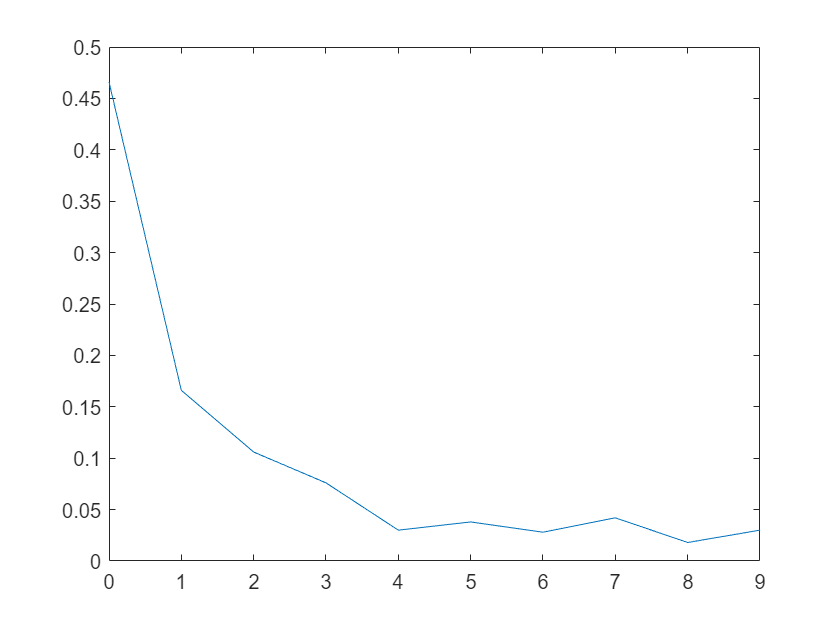

% Plot number of defaults
tbl = tabulate(n_defaults);
figure;
plot(tbl(:, 1), tbl(:, 3)/100);

title("Loss distribution")
xlabel('Number of defaults'); ylabel('Probability of number of defaults');

## Group A Case 1: 8:1:1

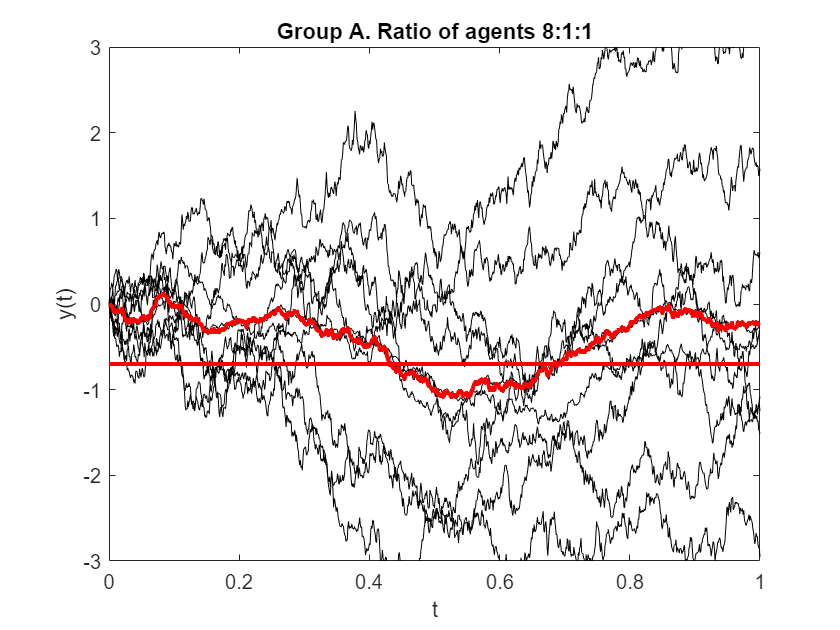

alpha = [repelem(1, 8, 1); repelem(10, 1, 1); repelem(100, 1, 1)];
sig = [repelem(2, 8, 1); repelem(1, 1, 1); repelem(0.5, 1, 1)];
f = @(t, y) alpha.*(mean(y) - y); 
g = @(t, y) sig;

% Specify Ito, set random seed
opts = sdeset('RandSeed', 1);         

% Use Euler-Maruyama to integrate SDEs
y = sde_euler(f, g, t, y0, opts);

ybar = mean(y, 2);

figure; 
plot(t, y, 'k')
hold on
% Average Line
plot(t, ybar, 'r', ...
    'LineWidth', 2)
hold on
% Default Line
plot(t, default_line, 'r', ...
    'LineWidth', 2)
hold off
ylim([-3 3])

title(['Group A. Ratio of agents 8:1:1']);
xlabel('t'); ylabel('y(t)');

## Group A Case 2: 1:8:1

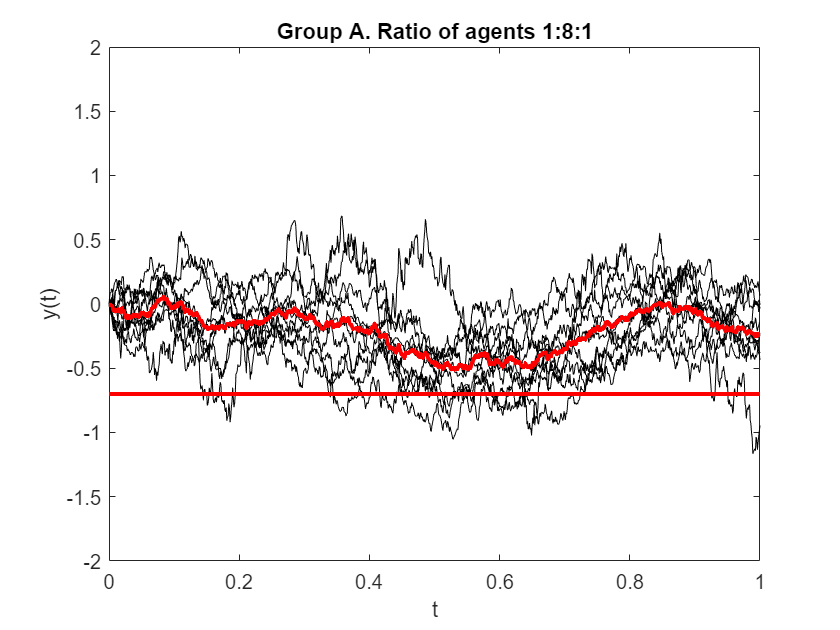

alpha = [repelem(1, 1, 1); repelem(10, 8, 1); repelem(100, 1, 1)];
sig = [repelem(2, 1, 1); repelem(1, 8, 1); repelem(0.5, 1, 1)];
f = @(t, y) alpha.*(mean(y) - y); 
g = @(t, y) sig;

% Specify Ito, set random seed
opts = sdeset('RandSeed', 1);         

% Use Euler-Maruyama to integrate SDEs
y = sde_euler(f, g, t, y0, opts);

ybar = mean(y, 2);

figure; 
plot(t, y, 'k')
hold on
% Average Line
plot(t, ybar, 'r', ...
    'LineWidth', 2)
hold on
% Default Line
plot(t, default_line, 'r', ...
    'LineWidth', 2)
hold off
ylim([-2 2])

title(['Group A. Ratio of agents 1:8:1']);
xlabel('t'); ylabel('y(t)');

## Group A Case 3: 1:1:8

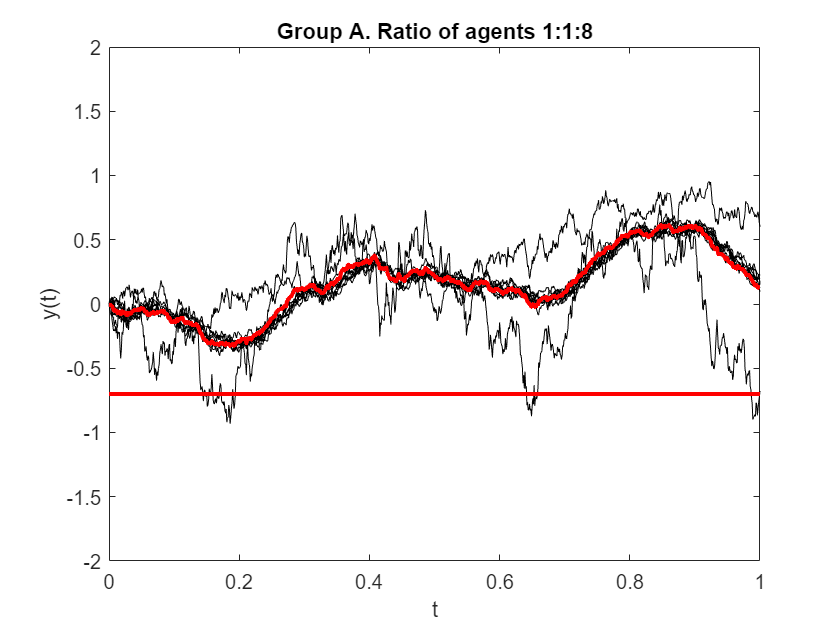

alpha = [repelem(1, 1, 1); repelem(10, 1, 1); repelem(100, 8, 1)];
sig = [repelem(2, 1, 1); repelem(1, 1, 1); repelem(0.5, 8, 1)];
f = @(t, y) alpha.*(mean(y) - y); 
g = @(t, y) sig;

% Specify Ito, set random seed
opts = sdeset('RandSeed', 1);         

% Use Euler-Maruyama to integrate SDEs
y = sde_euler(f, g, t, y0, opts);

ybar = mean(y, 2);

figure; 
plot(t, y, 'k')
hold on
% Average Line
plot(t, ybar, 'r', ...
    'LineWidth', 2)
hold on
% Default Line
plot(t, default_line, 'r', ...
    'LineWidth', 2)
hold off
ylim([-2 2])

title(['Group A. Ratio of agents 1:1:8']);
xlabel('t'); ylabel('y(t)');

## Group B Case 1: 8:1:1

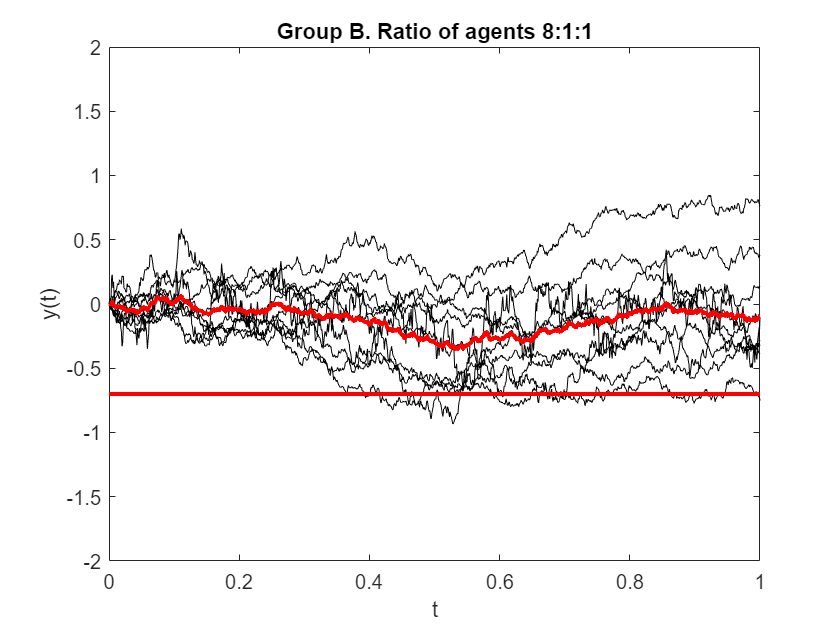

alpha = [repelem(1, 8, 1); repelem(10, 1, 1); repelem(100, 1, 1)];
sig = [repelem(0.5, 8, 1); repelem(1, 1, 1); repelem(2, 1, 1)];
f = @(t, y) alpha.*(mean(y) - y); 
g = @(t, y) sig;

% Specify Ito, set random seed
opts = sdeset('RandSeed', 1);         

% Use Euler-Maruyama to integrate SDEs
y = sde_euler(f, g, t, y0, opts);

ybar = mean(y, 2);

figure; 
plot(t, y, 'k')
hold on
% Average Line
plot(t, ybar, 'r', ...
    'LineWidth', 2)
hold on
% Default Line
plot(t, default_line, 'r', ...
    'LineWidth', 2)
hold off
ylim([-2 2])

title(['Group B. Ratio of agents 8:1:1']);
xlabel('t'); ylabel('y(t)');

## Group B Case 2: 1:8:1

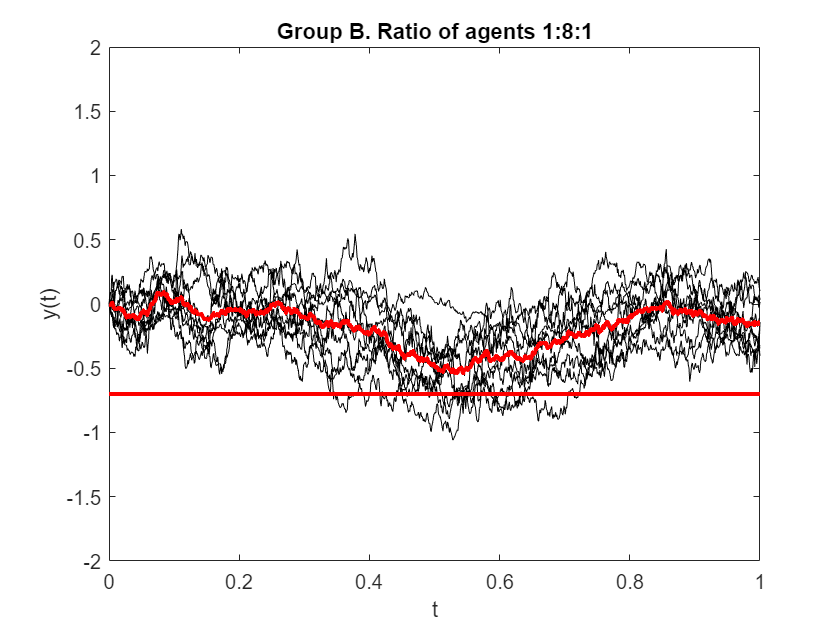

alpha = [repelem(1, 1, 1); repelem(10, 8, 1); repelem(100, 1, 1)];
sig = [repelem(0.5, 1, 1); repelem(1, 8, 1); repelem(2, 1, 1)];
f = @(t, y) alpha.*(mean(y) - y); 
g = @(t, y) sig;

% Specify Ito, set random seed
opts = sdeset('RandSeed', 1);         

% Use Euler-Maruyama to integrate SDEs
y = sde_euler(f, g, t, y0, opts);

ybar = mean(y, 2);

figure; 
plot(t, y, 'k')
hold on
% Average Line
plot(t, ybar, 'r', ...
    'LineWidth', 2)
hold on
% Default Line
plot(t, default_line, 'r', ...
    'LineWidth', 2)
hold off
ylim([-2 2])

title(['Group B. Ratio of agents 1:8:1']);
xlabel('t'); ylabel('y(t)');

## Group B Case 3: 1:1:8

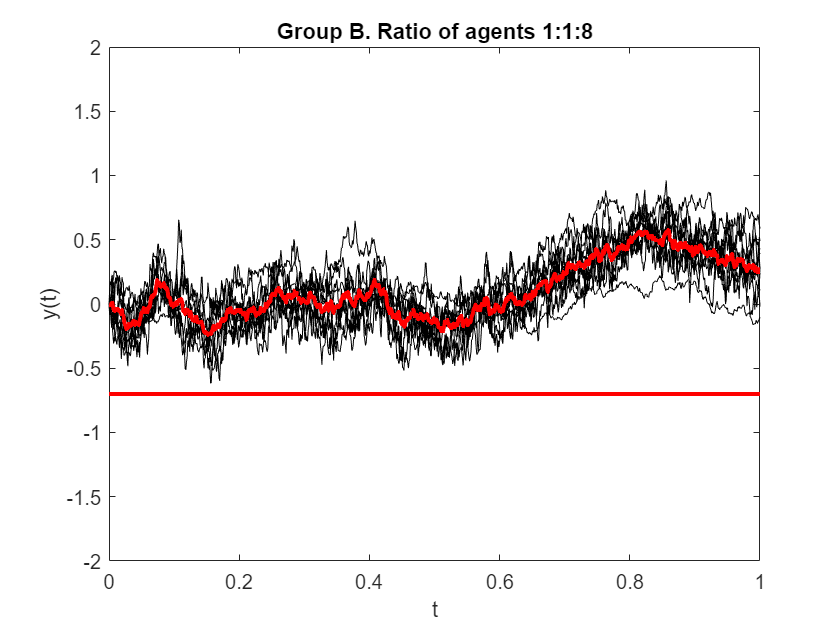

alpha = [repelem(1, 1, 1); repelem(10, 1, 1); repelem(100, 8, 1)];
sig = [repelem(0.5, 1, 1); repelem(1, 1, 1); repelem(2, 8, 1)];
f = @(t, y) alpha.*(mean(y) - y); 
g = @(t, y) sig;

% Specify Ito, set random seed
opts = sdeset('RandSeed', 1);         

% Use Euler-Maruyama to integrate SDEs
y = sde_euler(f, g, t, y0, opts);

ybar = mean(y, 2);

figure; 
plot(t, y, 'k')
hold on
% Average Line
plot(t, ybar, 'r', ...
    'LineWidth', 2)
hold on
% Default Line
plot(t, default_line, 'r', ...
    'LineWidth', 2)
hold off
ylim([-2 2])

title(['Group B. Ratio of agents 1:1:8']);
xlabel('t'); ylabel('y(t)');

## Group A Case 1: 8:1:1 - Varying N

% Simulate for different number of agents, from 10 to 300 with step 10.
Nvec = 10:10:300;          
% Initialise variable to capture event A
default = zeros(repeats, 1);
% Initialise variable to capture -1/N log P(A)
log_defaults = zeros(length(Nvec), 1);

% Loop over different number of agents
for N = Nvec
    y0 = zeros(N, 1);                           % Nx1 vector
    
    alpha = [repelem(1, 0.8.*N, 1); repelem(10, 0.1.*N, 1); repelem(100, 0.1.*N, 1)];
    sig = [repelem(0.5, 0.8.*N, 1); repelem(1, 0.1.*N, 1); repelem(2, 0.1.*N, 1)];
    f = @(t, y) alpha.*(mean(y) - y);
    g = @(t, y) sig;

    % Loop to get probability of default
    for rep = 1:repeats
       % Specify Ito, set random seed
       opts = sdeset('RandSeed', rep);  
       y = sde_euler(f, g, t, y0, opts);     
       default(rep) = min(mean(y)) <= eta;
    end

    log_defaults(N/10) = -1/N .* log(mean(default));
end

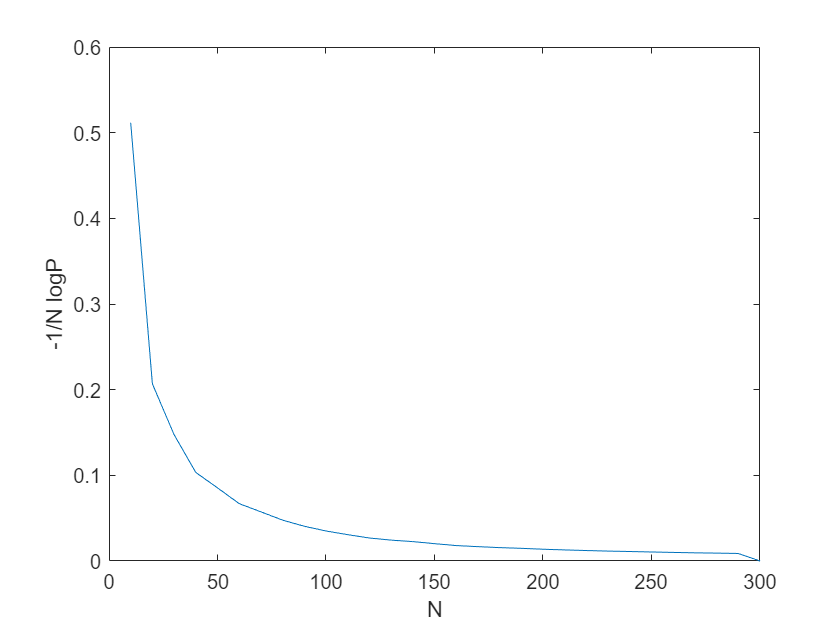

figure; 
plot(Nvec, log_defaults);
xlabel('N'); ylabel('-1/N logP');